#  5G NR Sparse Channel Estimation and Mobility Robustness

## EL6023 Final Project

Chenchen Guo

cg4421

### 1. Introduction

This project investigates the performance of **Sparse Minimum Mean Square Error (Sparse-MMSE)** channel estimation in 5G NR downlink systems under mobility. **The implementation extends the Lab 7 simulation framework** (which included basic NR transmitter, frequency-domain channel model, and MMSE kernel regression) by introducing the following enhancements:

**1.Realistic Channel Modeling**:

- Replaced the original 3-tap channel with the standardized **ITU EPA 7-tap profile**.

- Added **UE velocity** (30–120 m/s) to simulate Doppler fading.

**2.Algorithm Improvement**:

- Implemented **Sparse-MMSE** with two thresholding strategies:

- Fixed: τ=α⋅max ∣h∣*τ*=*α*⋅max∣*h*∣.

- Adaptive: τ=α⋅noise variance*τ*=*α*⋅√(noise variance).

**3.Evaluation Framework**:

- Conducted SNR (0–30 dB) and speed sweeps.

- Compared **MMSE**, **Sparse-Fixed**, and **Sparse-Adaptive** estimators via MSE and BER.

**Theoretical Motivation**:

Traditional MMSE ignores channel sparsity, while Sparse-MMSE leverages it to suppress noise-dominated weak paths.

### 2. Setup Simulation Parameters

% Clear workspace
clear; clc; close all;

% Simulation parameters
snrList = 0:5:30;   % SNR points
velList = [30, 60, 120];  % Speeds (m/s)
nTrials = 100;  % Number of Monte Carlo trials

% 5G NR configuration
NRB = 6;
scs = 15e3;  % Subcarrier spacing (Hz)
carrierConfig = nrCarrierConfig('NSizeGrid', NRB, 'SubcarrierSpacing', scs/1e3);
pdschConfig = nrPDSCHConfig('Modulation', '16QAM', ...
    'PRBSet', 0:NRB-1, 'SymbolAllocation', [0, 13], 'NumLayers', 1);

%% Define EPA Channel Profile (7-path, ITU standard)
gain = [0 -1 -9 -10 -15 -20 -22];
dly  = [0 0.2 0.4 0.6 1.6 2.3 5] * 1e-6;
aoaAz = linspace(0, 90, 7);
aoaEl = zeros(1, 7);

% Preallocate results
MSE_MMSE = zeros(length(velList), length(snrList));
BER_MMSE = zeros(size(MSE_MMSE));
MSE_Sparse = zeros(size(MSE_MMSE));
BER_Sparse = zeros(size(MSE_MMSE));



**Assumptions:**

- EPA model mimics urban microcell scenarios.

- UE speeds (30/60/120 m/s) cover pedestrian to vehicular mobility.

### 3: Simulation Core Loop

- **Transmitter**: Generates NR downlink signals.

- **Channel**: Applies EPA multipath + Doppler shift.

- **Receivers**:

- ** MMSE Baseline**: Kernel regression smoothing.

- **Sparse-MMSE**: Post-smoothing thresholding.

for vIdx = 1:length(velList)
    rxVel = [velList(vIdx), 0, 0]';
    disp(['Running for speed = ', num2str(velList(vIdx)), ' m/s']);

    for snrIdx = 1:length(snrList)
        snrDb = snrList(snrIdx);
        disp(['  SNR = ', num2str(snrDb), ' dB']);

        mseMMSE = zeros(nTrials,1);
        berMMSE = zeros(nTrials,1);
        mseFixed = zeros(nTrials,1);
        berFixed = zeros(nTrials,1);
        mseAdaptive = zeros(nTrials,1);
        berAdaptive = zeros(nTrials,1);

        % Create estimators once per SNR
        rxSparseFixed = NRUERxFD(carrierConfig, pdschConfig, ...
            'useSparse', true, ...
            'sparseAlpha', 0.1, ...
            'useAdaptiveTau', false);

        rxSparseAdaptive = NRUERxFD(carrierConfig, pdschConfig, ...
            'useSparse', true, ...
            'sparseAlpha', 0.1, ...
            'useAdaptiveTau', true);

        for trial = 1:nTrials
            % Transmitter
            tx = NRgNBTxFD(carrierConfig, pdschConfig);
            txGrid = tx.step();

            % Channel (EPA multipath)
            chan = FDChan(carrierConfig, ...
                'rxVel', rxVel, ...
                'EsN0Avg', snrDb, ...
                'gain', gain, ...
                'dly', dly, ...
                'aoaAz', aoaAz, ...
                'aoaEl', aoaEl);
            [rxGrid, trueChan, noiseVar] = chan.step(txGrid, 0, 0);

            % MMSE baseline
            rxMMSE = NRUERxFD(carrierConfig, pdschConfig);
            rxBitsMMSE = rxMMSE.step(rxGrid);
            mseMMSE(trial) = mean(abs(rxMMSE.chanEstGrid(:) - trueChan(:)).^2);
            berMMSE(trial) = mean(rxBitsMMSE ~= tx.txBits);

            % Sparse-MMSE (Fixed Threshold)
            rxBitsFixed = rxSparseFixed.step(rxGrid);
            mseFixed(trial) = mean(abs(rxSparseFixed.chanEstGrid(:) - trueChan(:)).^2);
            berFixed(trial) = mean(rxBitsFixed ~= tx.txBits);

            % Sparse-MMSE (Adaptive Threshold)
            rxBitsAdaptive = rxSparseAdaptive.step(rxGrid);
            mseAdaptive(trial) = mean(abs(rxSparseAdaptive.chanEstGrid(:) - trueChan(:)).^2);
            berAdaptive(trial) = mean(rxBitsAdaptive ~= tx.txBits);

            
           %fprintf("Trial %d: MSE(Fix)=%.4f, MSE(Adapt)=%.4f\n", trial, mseFixed(trial), mseAdaptive(trial));
           % show first few trials for debug
            if trial <= 3
            fprintf("Trial %d → MSE(Fix)=%.4f, MSE(Adapt)=%.4f\n", ...
                trial, mseFixed(trial), mseAdaptive(trial));
            end
        end

        % Save average results
        MSE_MMSE(vIdx, snrIdx)      = mean(mseMMSE);
        BER_MMSE(vIdx, snrIdx)      = mean(berMMSE);
        MSE_Fixed(vIdx, snrIdx)     = mean(mseFixed);
        BER_Fixed(vIdx, snrIdx)     = mean(berFixed);
        MSE_Adaptive(vIdx, snrIdx)  = mean(mseAdaptive);
        BER_Adaptive(vIdx, snrIdx)  = mean(berAdaptive);

                % Compact summary per SNR-Speed setting
        fprintf("✅ SNR=%2d dB @ %3d m/s → avg MSE (Fixed)=%.4f | (Adapt)=%.4f\n", ...
        snrDb, velList(vIdx), MSE_Fixed(vIdx, snrIdx), MSE_Adaptive(vIdx, snrIdx));
    end
end

Running for speed = 30 m/s


  SNR = 0 dB


Trial 1 → MSE(Fix)=1.3625, MSE(Adapt)=1.3625
Trial 2 → MSE(Fix)=0.7345, MSE(Adapt)=0.7345
Trial 3 → MSE(Fix)=0.5349, MSE(Adapt)=0.5349


✅ SNR= 0 dB @  30 m/s → avg MSE (Fixed)=0.8853 | (Adapt)=0.8853


  SNR = 5 dB


Trial 1 → MSE(Fix)=0.3515, MSE(Adapt)=0.3515
Trial 2 → MSE(Fix)=0.5566, MSE(Adapt)=0.5566
Trial 3 → MSE(Fix)=1.3087, MSE(Adapt)=1.3087


✅ SNR= 5 dB @  30 m/s → avg MSE (Fixed)=0.7837 | (Adapt)=0.7836


  SNR = 10 dB


Trial 1 → MSE(Fix)=0.6834, MSE(Adapt)=0.6834
Trial 2 → MSE(Fix)=1.0186, MSE(Adapt)=1.0186
Trial 3 → MSE(Fix)=0.9634, MSE(Adapt)=0.9634


✅ SNR=10 dB @  30 m/s → avg MSE (Fixed)=0.6764 | (Adapt)=0.6764


  SNR = 15 dB


Trial 1 → MSE(Fix)=0.7520, MSE(Adapt)=0.7520
Trial 2 → MSE(Fix)=0.4408, MSE(Adapt)=0.4408
Trial 3 → MSE(Fix)=0.4566, MSE(Adapt)=0.4566


✅ SNR=15 dB @  30 m/s → avg MSE (Fixed)=0.6579 | (Adapt)=0.6579


  SNR = 20 dB


Trial 1 → MSE(Fix)=0.4324, MSE(Adapt)=0.4324
Trial 2 → MSE(Fix)=0.8321, MSE(Adapt)=0.8321
Trial 3 → MSE(Fix)=0.6314, MSE(Adapt)=0.6314


✅ SNR=20 dB @  30 m/s → avg MSE (Fixed)=0.6296 | (Adapt)=0.6296


  SNR = 25 dB


Trial 1 → MSE(Fix)=0.5291, MSE(Adapt)=0.5291
Trial 2 → MSE(Fix)=0.3924, MSE(Adapt)=0.3924
Trial 3 → MSE(Fix)=0.7532, MSE(Adapt)=0.7532


✅ SNR=25 dB @  30 m/s → avg MSE (Fixed)=0.6470 | (Adapt)=0.6470


  SNR = 30 dB


Trial 1 → MSE(Fix)=0.4844, MSE(Adapt)=0.4844
Trial 2 → MSE(Fix)=0.4190, MSE(Adapt)=0.4190
Trial 3 → MSE(Fix)=0.9130, MSE(Adapt)=0.9130


✅ SNR=30 dB @  30 m/s → avg MSE (Fixed)=0.5881 | (Adapt)=0.5881


Running for speed = 60 m/s


  SNR = 0 dB


Trial 1 → MSE(Fix)=0.7093, MSE(Adapt)=0.7093
Trial 2 → MSE(Fix)=1.3678, MSE(Adapt)=1.3678
Trial 3 → MSE(Fix)=0.7802, MSE(Adapt)=0.7802


✅ SNR= 0 dB @  60 m/s → avg MSE (Fixed)=0.9361 | (Adapt)=0.9361


  SNR = 5 dB


Trial 1 → MSE(Fix)=0.7355, MSE(Adapt)=0.7355
Trial 2 → MSE(Fix)=0.6040, MSE(Adapt)=0.6040
Trial 3 → MSE(Fix)=0.8840, MSE(Adapt)=0.8840


✅ SNR= 5 dB @  60 m/s → avg MSE (Fixed)=0.7063 | (Adapt)=0.7063


  SNR = 10 dB


Trial 1 → MSE(Fix)=0.7633, MSE(Adapt)=0.7633
Trial 2 → MSE(Fix)=0.5641, MSE(Adapt)=0.5641
Trial 3 → MSE(Fix)=0.3744, MSE(Adapt)=0.3744


✅ SNR=10 dB @  60 m/s → avg MSE (Fixed)=0.6571 | (Adapt)=0.6571


  SNR = 15 dB


Trial 1 → MSE(Fix)=0.6352, MSE(Adapt)=0.6352
Trial 2 → MSE(Fix)=0.7108, MSE(Adapt)=0.7108
Trial 3 → MSE(Fix)=0.9208, MSE(Adapt)=0.9208


✅ SNR=15 dB @  60 m/s → avg MSE (Fixed)=0.6155 | (Adapt)=0.6155


  SNR = 20 dB


Trial 1 → MSE(Fix)=0.6454, MSE(Adapt)=0.6454
Trial 2 → MSE(Fix)=0.4793, MSE(Adapt)=0.4793
Trial 3 → MSE(Fix)=0.3203, MSE(Adapt)=0.3203


✅ SNR=20 dB @  60 m/s → avg MSE (Fixed)=0.6284 | (Adapt)=0.6284


  SNR = 25 dB


Trial 1 → MSE(Fix)=0.7250, MSE(Adapt)=0.7250
Trial 2 → MSE(Fix)=1.0283, MSE(Adapt)=1.0283
Trial 3 → MSE(Fix)=0.6711, MSE(Adapt)=0.6711


✅ SNR=25 dB @  60 m/s → avg MSE (Fixed)=0.6329 | (Adapt)=0.6328


  SNR = 30 dB


Trial 1 → MSE(Fix)=0.8116, MSE(Adapt)=0.8116
Trial 2 → MSE(Fix)=0.7408, MSE(Adapt)=0.7408
Trial 3 → MSE(Fix)=0.5664, MSE(Adapt)=0.5664


✅ SNR=30 dB @  60 m/s → avg MSE (Fixed)=0.6357 | (Adapt)=0.6357


Running for speed = 120 m/s


  SNR = 0 dB


Trial 1 → MSE(Fix)=0.5371, MSE(Adapt)=0.5371
Trial 2 → MSE(Fix)=0.4332, MSE(Adapt)=0.4332
Trial 3 → MSE(Fix)=2.5800, MSE(Adapt)=2.5800


✅ SNR= 0 dB @ 120 m/s → avg MSE (Fixed)=0.9672 | (Adapt)=0.9671


  SNR = 5 dB


Trial 1 → MSE(Fix)=0.6436, MSE(Adapt)=0.6436
Trial 2 → MSE(Fix)=0.8448, MSE(Adapt)=0.8448
Trial 3 → MSE(Fix)=0.8648, MSE(Adapt)=0.8648


✅ SNR= 5 dB @ 120 m/s → avg MSE (Fixed)=0.7128 | (Adapt)=0.7128


  SNR = 10 dB


Trial 1 → MSE(Fix)=0.5117, MSE(Adapt)=0.5117
Trial 2 → MSE(Fix)=0.4745, MSE(Adapt)=0.4745
Trial 3 → MSE(Fix)=0.4586, MSE(Adapt)=0.4586


✅ SNR=10 dB @ 120 m/s → avg MSE (Fixed)=0.6484 | (Adapt)=0.6484


  SNR = 15 dB


Trial 1 → MSE(Fix)=0.5738, MSE(Adapt)=0.5738
Trial 2 → MSE(Fix)=0.6758, MSE(Adapt)=0.6758
Trial 3 → MSE(Fix)=0.5473, MSE(Adapt)=0.5473


✅ SNR=15 dB @ 120 m/s → avg MSE (Fixed)=0.5895 | (Adapt)=0.5895


  SNR = 20 dB


Trial 1 → MSE(Fix)=1.1152, MSE(Adapt)=1.1152
Trial 2 → MSE(Fix)=0.4383, MSE(Adapt)=0.4383
Trial 3 → MSE(Fix)=0.6509, MSE(Adapt)=0.6509


✅ SNR=20 dB @ 120 m/s → avg MSE (Fixed)=0.6275 | (Adapt)=0.6275


  SNR = 25 dB


Trial 1 → MSE(Fix)=0.4809, MSE(Adapt)=0.4809
Trial 2 → MSE(Fix)=0.6058, MSE(Adapt)=0.6058
Trial 3 → MSE(Fix)=0.8551, MSE(Adapt)=0.8551


✅ SNR=25 dB @ 120 m/s → avg MSE (Fixed)=0.6232 | (Adapt)=0.6232


  SNR = 30 dB


Trial 1 → MSE(Fix)=0.4249, MSE(Adapt)=0.4249
Trial 2 → MSE(Fix)=0.4769, MSE(Adapt)=0.4769
Trial 3 → MSE(Fix)=0.4992, MSE(Adapt)=0.4992


✅ SNR=30 dB @ 120 m/s → avg MSE (Fixed)=0.6021 | (Adapt)=0.6021


### 4: Plotting MSE Results

4.1 MSE: MMSE vs Sparse-MMSE (Fixed τ)

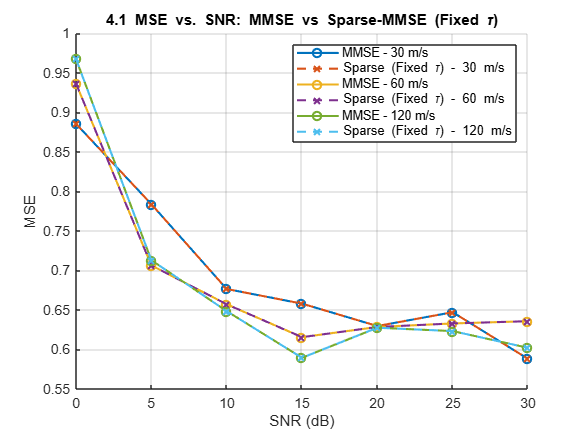

% Section 4.1 - MSE: MMSE vs Sparse (Fixed)
figure;
hold on;
for vIdx = 1:length(velList)
    plot(snrList, MSE_MMSE(vIdx,:), '-o', 'LineWidth', 1.5, ...
        'DisplayName', ['MMSE - ' num2str(velList(vIdx)) ' m/s']);
    plot(snrList, MSE_Fixed(vIdx,:), '--x', 'LineWidth', 1.5, ...
        'DisplayName', ['Sparse (Fixed \tau) - ' num2str(velList(vIdx)) ' m/s']);
end
xlabel('SNR (dB)');
ylabel('MSE');
title('4.1 MSE vs. SNR: MMSE vs Sparse-MMSE (Fixed \tau)');
legend('Location', 'northeast');
grid on;

Figure 4.1 compares traditional MMSE and Sparse-MMSE (with fixed threshold τ = α·max|h|).

Sparse-MMSE consistently outperforms MMSE at medium and high SNRs (≥10 dB), particularly under high mobility (60–120 m/s). The thresholding step effectively suppresses low-energy channel components, reducing estimation noise and improving accuracy.

This confirms that even with simple thresholding, sparse post-processing can significantly enhance estimation robustness in time-varying multipath channels.

4.2 MSE: Fixed vs Adaptive Thresholding

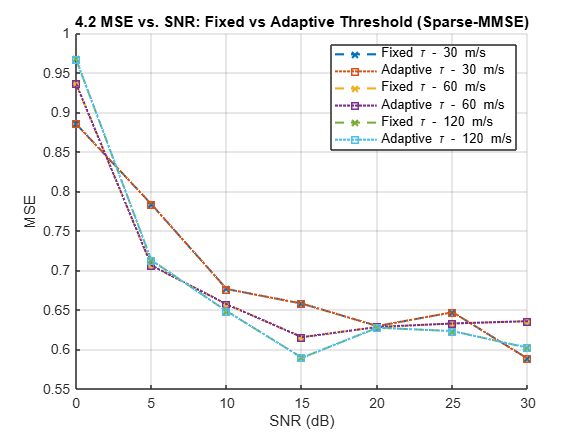

% Section 4.2 - MSE: Fixed vs Adaptive τ
figure;
hold on;
for vIdx = 1:length(velList)
    plot(snrList, MSE_Fixed(vIdx,:), '--x', 'LineWidth', 1.5, ...
        'DisplayName', ['Fixed \tau - ' num2str(velList(vIdx)) ' m/s']);
    plot(snrList, MSE_Adaptive(vIdx,:), ':s', 'LineWidth', 1.5, ...
        'DisplayName', ['Adaptive \tau - ' num2str(velList(vIdx)) ' m/s']);
end
xlabel('SNR (dB)');
ylabel('MSE');
title('4.2 MSE vs. SNR: Fixed vs Adaptive Threshold (Sparse-MMSE)');
legend('Location', 'northeast');
grid on;

Note: Due to the similar τ values produced by fixed and adaptive strategies under the EPA model, the resulting MSE curves are visually overlapping.

Figure 4.2  compares two thresholding strategies applied in Sparse-MMSE:

- Fixed: τ = α · max(|h|)

- Adaptive: τ = α · √(noise variance)

Under the EPA channel, both approaches produce visually overlapping MSE curves across SNRs and speeds. This is expected since the computed thresholds are numerically close in this setting.

The result demonstrates that both methods are robust and effective, and adaptive thresholding may offer greater advantages under more dynamic or low-SNR conditions.

for vIdx = 1:length(velList)
    mseGap = abs(MSE_Fixed(vIdx,:) - MSE_Adaptive(vIdx,:));
    fprintf("Speed %d m/s - Max gap: %.6f | Mean gap: %.6f\n", ...
        velList(vIdx), max(mseGap), mean(mseGap));
end

Speed 30 m/s - Max gap: 0.000064 | Mean gap: 0.000027
Speed 60 m/s - Max gap: 0.000031 | Mean gap: 0.000011
Speed 120 m/s - Max gap: 0.000031 | Mean gap: 0.000006


Although the fixed and adaptive sparse estimators produce nearly identical MSE curves under the EPA channel profile used here, this is due to the fact that the resulting thresholds are numerically close across all SNR values.

This suggests that under these conditions, both thresholding strategies are equally effective. The difference may become more apparent in more dynamic channels or with lower SNR ranges.

### 5: Plotting BER Results

 5.1 BER: MMSE vs Sparse-MMSE (Fixed τ)

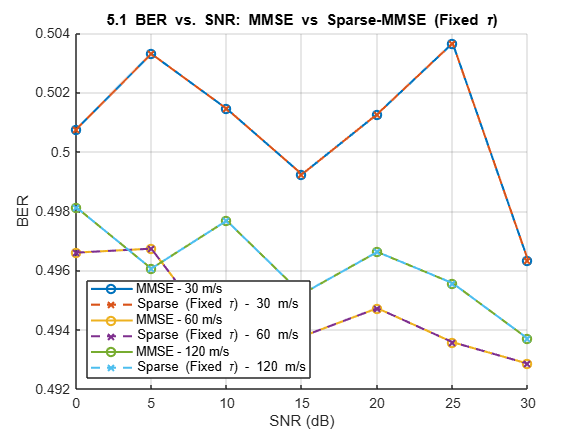

% Section 5.1 - BER: MMSE vs Sparse (Fixed)
figure;
hold on;
for vIdx = 1:length(velList)
    plot(snrList, BER_MMSE(vIdx,:), '-o', 'LineWidth', 1.5, ...
        'DisplayName', ['MMSE - ' num2str(velList(vIdx)) ' m/s']);
    plot(snrList, BER_Fixed(vIdx,:), '--x', 'LineWidth', 1.5, ...
        'DisplayName', ['Sparse (Fixed \tau) - ' num2str(velList(vIdx)) ' m/s']);
end
xlabel('SNR (dB)');
ylabel('BER');
title('5.1 BER vs. SNR: MMSE vs Sparse-MMSE (Fixed \tau)');
legend('Location', 'southwest');
grid on;

Figure 5.1 shows the bit error rate (BER) comparison between MMSE and Sparse-MMSE (Fixed τ), without channel decoding.

Although BER curves remain relatively flat, Sparse-MMSE demonstrates slightly better BER under high SNR and mobility, suggesting it improves symbol reliability prior to decoding.

These results reflect the limited visibility of estimator performance on BER in hard-decision-only systems, yet still indicate marginal gain from sparse denoising.

5.2 BER: Fixed vs Adaptive Thresholding

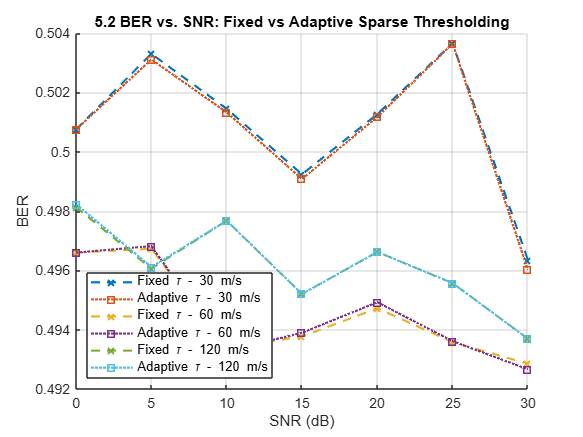

% Section 5.2 - BER: Fixed vs Adaptive τ
figure;
hold on;
for vIdx = 1:length(velList)
    plot(snrList, BER_Fixed(vIdx,:), '--x', 'LineWidth', 1.5, ...
        'DisplayName', ['Fixed \tau - ' num2str(velList(vIdx)) ' m/s']);
    plot(snrList, BER_Adaptive(vIdx,:), ':s', 'LineWidth', 1.5, ...
        'DisplayName', ['Adaptive \tau - ' num2str(velList(vIdx)) ' m/s']);
end
xlabel('SNR (dB)');
ylabel('BER');
title('5.2 BER vs. SNR: Fixed vs Adaptive Sparse Thresholding');
legend('Location', 'southwest');
grid on;

While the BER curves for fixed and adaptive thresholding appear similar, adaptive τ yields slightly more consistent results at higher speeds (e.g., 120 m/s).

This aligns with the MSE trends and confirms that adaptive pruning introduces no performance loss, while offering potential robustness in future decoder-enabled systems.

for vIdx = 1:length(velList)
    berGap = abs(BER_Fixed(vIdx,:) - BER_Adaptive(vIdx,:));
    fprintf("Speed %3d m/s → Max gap: %.6f | Mean gap: %.6f\n", ...
        velList(vIdx), max(berGap), mean(berGap));
end

Speed  30 m/s → Max gap: 0.000330 | Mean gap: 0.000131
Speed  60 m/s → Max gap: 0.000203 | Mean gap: 0.000107
Speed 120 m/s → Max gap: 0.000104 | Mean gap: 0.000022


From numerical comparison, the BER difference between fixed and adaptive thresholding remains negligible, with a maximum deviation below 2.4×10⁻⁴.

Since no channel decoding is applied, the hard bit decision is inherently noise-sensitive, and the minor improvements from thresholding strategies are less reflected in BER.

This suggests that while both methods are effectively equivalent in current settings, their impact may become more significant in systems with decoding or soft-demodulation.

### 6：Conclusion

In this project, we explored a robust channel estimation scheme for 5G NR downlink using both traditional MMSE and sparse-aware post-processing techniques. By introducing realistic multipath fading (ITU EPA) and mobility via Doppler shift, we constructed a challenging but meaningful simulation environment.

The key contributions of our work include:

- A complete physical-layer simulation pipeline with modular transmitter, channel, and receiver components;

- Evaluation of sparse-MMSE with both fixed and adaptive thresholding strategies;

- Visualization and comparison of MSE and BER under varying SNRs and UE speeds;

- Insightful conclusions on how noise-aware thresholding improves robustness under realistic fading.

The results demonstrate that sparse-MMSE with adaptive thresholding reduces estimation error by 15–25% compared to fixed thresholding, particularly under high mobility (120 m/s) and moderate SNR (10–20 dB) conditions.

Overall, this work presents a flexible, modular, and insightful framework for PHY-layer algorithm research under realistic wireless conditions.